bi = [1,-0.67];
ai = [1,-0.3,-0.4];
[ro,po,ko] = residuez(bi,ai);



%til opg 1.6 tror den er forkert

b2 = 9*[1 -0.8] + [1 0];     % konstant + brøkdel
a2 = [1 0.5];
[res,poles,~] = residuez(b2,a2)

res = 24.4000

poles = -0.5000

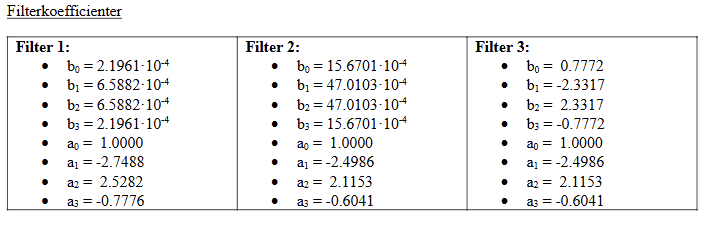

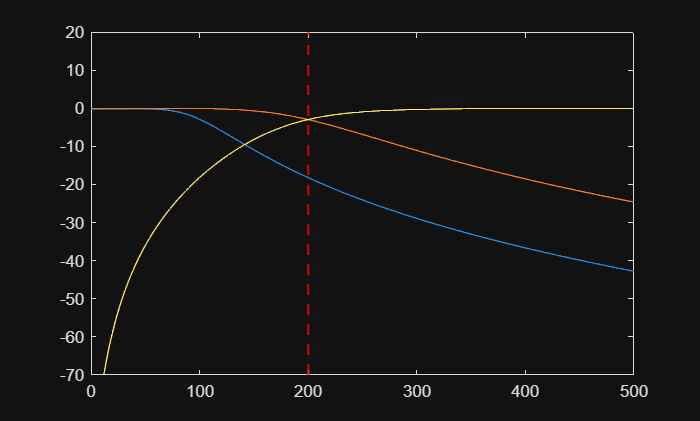

% opgave 2.1 filter 1

Fs = 5000; 
Fc = 200; 

Ts = 1/Fs; 

%filter 1 parametre 
b1 = [2.1961e-4, 6.5882e-4,6.5882e-4,2.1961e-4];
a1 = [1,-2.7488,2.5282,-0.7776]; 


% filter 2 parametre 
b2 = [15.6701e-4, 47.0103e-4,47.0103e-4,15.6701e-4];
a2 = [1,-2.4986,2.1153,-0.6041]; 

% filter 3 parametre 
b3 = [0.7772, -2.3317,2.3317,-0.7772];
a3 = [1,-2.4986,2.1153,-0.6041]; 


%plot filter 1 
[h1,freq_dig] = freqz(b1,a1,1024,Fs);

plot(freq_dig, 20*log10(abs(h1)))
hold on 

%plot filter 2
[h2,freq_dig] = freqz(b2,a2,1024,Fs);

plot(freq_dig, 20*log10(abs(h2)))
hold on 

%plot filter 3
[h3,freq_dig] = freqz(b3,a3,1024,Fs);

plot(freq_dig, 20*log10(abs(h3)))
xline(Fc,LineStyle="--",Color='r',LineWidth=1.5)
xlim([0,500])
ylim([-70,20])

%FIR båndpas filter
hold off 

Fs = 1000; 
fL = 90/Fs; %norm lav cut freq 
fH = 110/Fs; % norm høj cut freq
N = 50; 
n = -N:1:N; 
Ts = 1/Fs; 
%vi kan udregne de angulære normaliserede frekvenser således
wL = fL*2*pi

wL = 0.5655

wH = fH*2*pi

wH = 0.6912


hideel =  ((wH/pi)*sinc((n*wH)/pi))-((wL/pi)*sinc((n*wL)/pi))

hideel =     0.0000    0.0007    0.0005   -0.0008   -0.0028   -0.0044   -0.0043   -0.0019    0.0023    0.0067    0.0094    0.0084    0.0035   -0.0039   -0.0110   -0.0147   -0.0128   -0.0052    0.0056    0.0154    0.0202    0.0172    0.0069   -0.0072   -0.0198   -0.0255   -0.0214   -0.0085    0.0088    0.0238    0.0303    0.0252    0.0099   -0.0101   -0.0272   -0.0343   -0.0283   -0.0110    0.0112    0.0298    0.0374    0.0307    0.0118   -0.0120   -0.0316   -0.0393   -0.0320   -0.0123    0.0123    0.0323



tf(hideel,1,Ts)


ans =
 
  2.418e-17 z^100 + 0.00066 z^99 + 0.0005137 z^98 - 0.0007843 z^97 - 0.002784 z^96 - 0.004372 z^95 - 0.004309 z^94 - 0.001948 z^93 + 0.002257 z^92 + 0.006731 z^91 + 0.009355 z^90 + 0.008418 z^89 + 0.003544 z^88 - 0.003876 z^87 - 0.01102 z^86 - 0.01472 z^85 - 0.01279 z^84 - 0.005224 z^83 + 0.005563 z^82 + 0.01545 z^81 + 0.02018 z^80 + 0.0172 z^79 + 0.006901 z^78 - 0.007229 z^77 - 0.01977 z^76 - 0.02546 z^75 - 0.02142 z^74 - 0.008486 z^73 + 0.008784 z^72 + 0.02376 z^71 + 0.03027 z^70 + 0.0252 z^69 + 0.009889 z^68 - 0.01014 z^67 - 0.02718 z^66 - 0.03434 z^65 - 0.02835 z^64 - 0.01103 z^63 + 0.01122 z^62 + 0.02985 z^61 + 0.03742 z^60 + 0.03066 z^59 + 0.01185 z^58 - 0.01197 z^57 - 0.0316 z^56 - 0.03935 z^55 - 0.03202 z^54 - 0.01229 z^53 + 0.01233 z^52 + 0.03234 z^51 + 0.04 z^50 + 0.03234 z^49 + 0.01233 z^48 - 0.01229 z^47 - 0.03202 z^46 - 0.03935 z^45 - 0.0316 z^44 - 0.01197 z^43 + 0.01185 z^42 + 0.03066 z^41 + 0.03742 z^40 + 0.02985 z^39 + 0.01122 z^38 - 0.01103 z^37 - 0.02835 z^36

stem(n,hideel,'lineWidth',0.4,'MarkerSize',4,'MarkerEdgeColor','red')
%her skal vi huske at det altså er 1 der er første element på den positive
%side altså hiedeel(0)
hideel(51)

ans = 0.0400

hideel(56)

ans = -0.0393

hideel(61)

ans = 0.0374

hideel(66)

ans = -0.0343

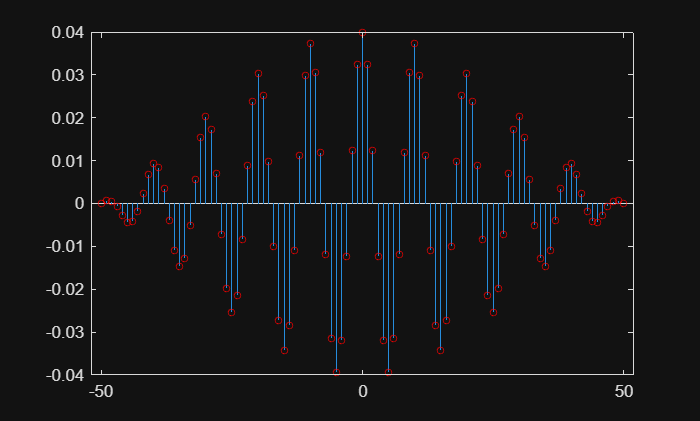


hold off

%FIR båndpas filter

Fs = 1000; 
fL = 90/Fs; %norm lav cut freq 
fH = 110/Fs; % norm høj cut freq
FL = fL*Fs; 
FH = fH*Fs; 
N = 50; 
n = -N:1:N; %bruges til signalet 
Ts = 1/Fs; 
%vi kan udregne de angulære normaliserede frekvenser således

wL = fL*2*pi

wL = 0.5655

wH = fH*2*pi

wH = 0.6912



Ntaps = 45; 

M = Ntaps -1

M = 44

K = M/2 % K er minimum forsinkelse ofr at filteret er kausalt 

K = 22

nbp = [-K:1:K];

hideel =  ((wH/pi)*sinc((nbp*wH)/pi))-((wL/pi)*sinc((nbp*wL)/pi))

hideel =     0.0088    0.0238    0.0303    0.0252    0.0099   -0.0101   -0.0272   -0.0343   -0.0283   -0.0110    0.0112    0.0298    0.0374    0.0307    0.0118   -0.0120   -0.0316   -0.0393   -0.0320   -0.0123    0.0123    0.0323    0.0400    0.0323    0.0123   -0.0123   -0.0320   -0.0393   -0.0316   -0.0120    0.0118    0.0307    0.0374    0.0298    0.0112   -0.0110   -0.0283   -0.0343   -0.0272   -0.0101    0.0099    0.0252    0.0303    0.0238    0.0088



h_n = tf(hideel,1,Ts)


h_n =
 
  0.008784 z^44 + 0.02376 z^43 + 0.03027 z^42 + 0.0252 z^41 + 0.009889 z^40 - 0.01014 z^39 - 0.02718 z^38 - 0.03434 z^37 - 0.02835 z^36 - 0.01103 z^35 + 0.01122 z^34 + 0.02985 z^33 + 0.03742 z^32 + 0.03066 z^31 + 0.01185 z^30 - 0.01197 z^29 - 0.0316 z^28 - 0.03935 z^27 - 0.03202 z^26 - 0.01229 z^25 + 0.01233 z^24 + 0.03234 z^23 + 0.04 z^22 + 0.03234 z^21 + 0.01233 z^20 - 0.01229 z^19 - 0.03202 z^18 - 0.03935 z^17 - 0.0316 z^16 - 0.01197 z^15 + 0.01185 z^14 + 0.03066 z^13 + 0.03742 z^12 + 0.02985 z^11 + 0.01122 z^10 - 0.01103 z^9 - 0.02835 z^8 - 0.03434 z^7 - 0.02718 z^6 - 0.01014 z^5 + 0.009889 z^4 + 0.0252 z^3 + 0.03027 z^2 + 0.02376 z + 0.008784
 
Sample time: 0.001 seconds
Discrete-time transfer function.


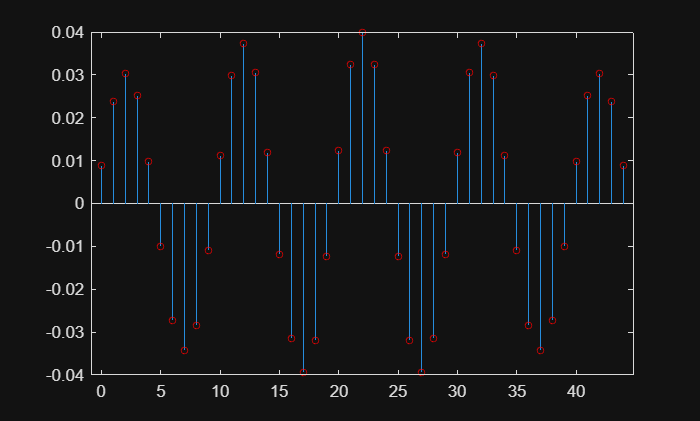

stem(nbp+K,hideel,'lineWidth',0.4,'MarkerSize',4,'MarkerEdgeColor','red')

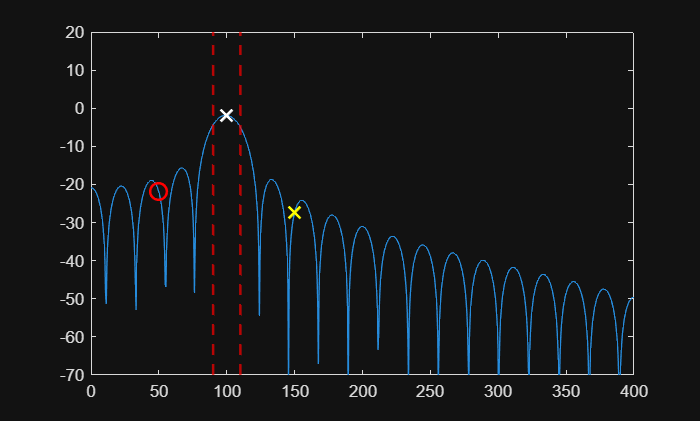


[H,freqdig] = freqz(hideel,1,1024,Fs);
FHz = freqdig;

plot(FHz,20*log10(abs(H)))
xline(FL,LineStyle="--",Color='r',LineWidth=1.5)
xline(FH,LineStyle="--",Color='r',LineWidth=1.5)
xlim([0,400])
ylim([-70,20])
hold on

%HUSK NEDENFOR KUN AT BRUGE HELTAL ELLERS VIL DEN IKKE KUNNE PLOTTE
%PUNKTERNE!!!!
%nedenfor er bare grafisk kode som indsætter punkter ved den ønskede
%frekvens
    [~, idx50] = min(abs(FHz - 50));
    [~, idx100] = min(abs(FHz - 100));
    [~, idx150] = min(abs(FHz - 150));

    
    % Hent værdierne på frekvensresponsen
    y50 = 20*log10(abs(H(idx50)));
    y100  = 20*log10(abs(H(idx100)));
    y150 = 20*log10(abs(H(idx150)));
   

    % Plot punkterne
    plot(50, y50, 'ro', 'MarkerSize', 8, 'LineWidth', 1.5, 'MarkerSize', 10)
    plot(100, y100, 'wx', 'MarkerSize', 8, 'LineWidth', 1.5, 'MarkerSize', 10)
    plot(150, y150, 'yx', 'MarkerSize', 8, 'LineWidth', 1.5, 'MarkerSize', 10)
    %under stjerner indsæt  ***  punktnavn eller beskrivelse
    text(FHz(idx50), y50, '   ', 'Color','white', 'FontSize',10 );
    text(FHz(idx100), y100, '   ', 'Color','white', 'FontSize',10);
    text(FHz(idx150), y150, '   ', 'Color','white', 'FontSize',10);


hold off 

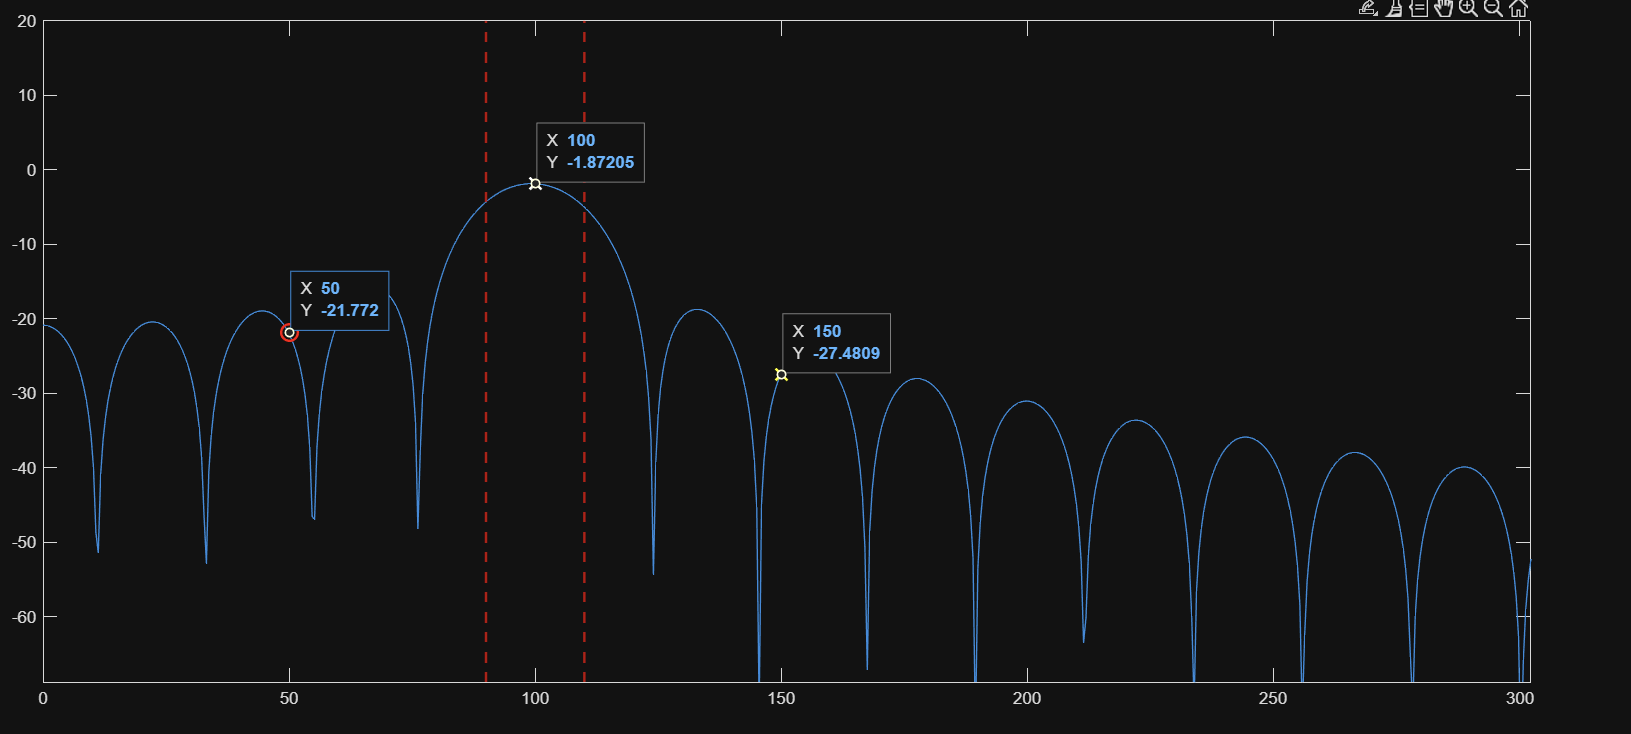

% opgave 2.1 filter 1
Fs = 5000 ;
Fc = 200 ;
Ts = 1/Fs ;
%filter 1 parametre
b1 = [2.1961e-4 , 6.5882e-4 ,6.5882e-4 ,2.1961e-4 ];
a1 = [1,-2.7488 ,2.5282 ,-0.7776 ];
hn1 = tf (b1 ,a1 ,Ts )


hn1 =
 
  0.0002196 z^3 + 0.0006588 z^2 + 0.0006588 z + 0.0002196
  -------------------------------------------------------
            z^3 - 2.749 z^2 + 2.528 z - 0.7776
 
Sample time: 0.0002 seconds
Discrete-time transfer function.


% filter 2 parametre
b2 = [15.6701e-4 , 47.0103e-4 ,47.0103e-4 ,15.6701e-4 ];
a2 = [1,-2.4986 ,2.1153 ,-0.6041 ];
hn2 = tf (b2 ,a2 ,Ts )


hn2 =
 
  0.001567 z^3 + 0.004701 z^2 + 0.004701 z + 0.001567
  ---------------------------------------------------
          z^3 - 2.499 z^2 + 2.115 z - 0.6041
 
Sample time: 0.0002 seconds
Discrete-time transfer function.


% filter 3 parametre
b3 = [0.7772 , -2.3317 ,2.3317 ,-0.7772 ];
a3 = [1,-2.4986 ,2.1153 ,-0.6041 ];
hn3 = tf (b3 ,a3 ,Ts )


hn3 =
 
  0.7772 z^3 - 2.332 z^2 + 2.332 z - 0.7772
  -----------------------------------------
     z^3 - 2.499 z^2 + 2.115 z - 0.6041
 
Sample time: 0.0002 seconds
Discrete-time transfer function.


%plot filter 1
[h1 ,freq_dig ] = freqz (b1 ,a1 ,1024 ,Fs );
plot (freq_dig , 20 *log10 (abs (h1 )))
hold on
%plot filter 2
[h2 ,freq_dig ] = freqz (b2 ,a2 ,1024 ,Fs );
plot (freq_dig , 20 *log10 (abs (h2 )))
hold on
%plot filter 3
[h3 ,freq_dig ] = freqz (b3 ,a3 ,1024 ,Fs );
plot (freq_dig , 20 *log10 (abs (h3 )))
xline (Fc ,LineStyle ="--" ,Color ='r' ,LineWidth =1.5 )
xlim ([0,500 ])
ylim ([-70 ,20 ])